Nx = 110;

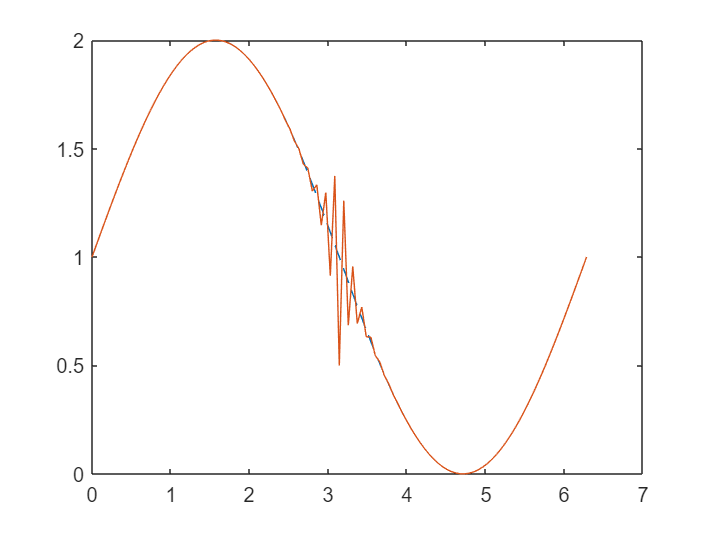

x = linspace(0, 2*pi, Nx+1);
x = x(1:end-1);
f_true = 1 + sin(x);
eps = (-1).^(0:Nx-1) .* exp(-8*abs(x - pi)) * .5;
f = f_true + eps;

x_pl = [x, 2*pi];
f_true = [f_true, f_true(1)];
f = [f, f(1)];

figure
plot(x_pl, f_true, '--');
hold on;
plot(x_pl, f)
hold off;

Compact smoothing coefficients

a = 1.135;
b = 2-a;
c = 1;

Symbol of compact operator

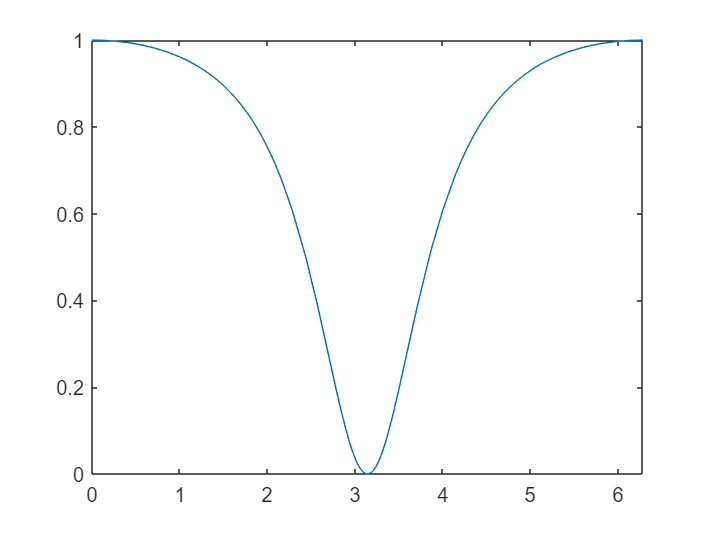

sigma = @(w) (1 + c*cos(w)) ./ (a + b*cos(w));

figure
fplot(sigma, [0, 2*pi]);

Smoothing

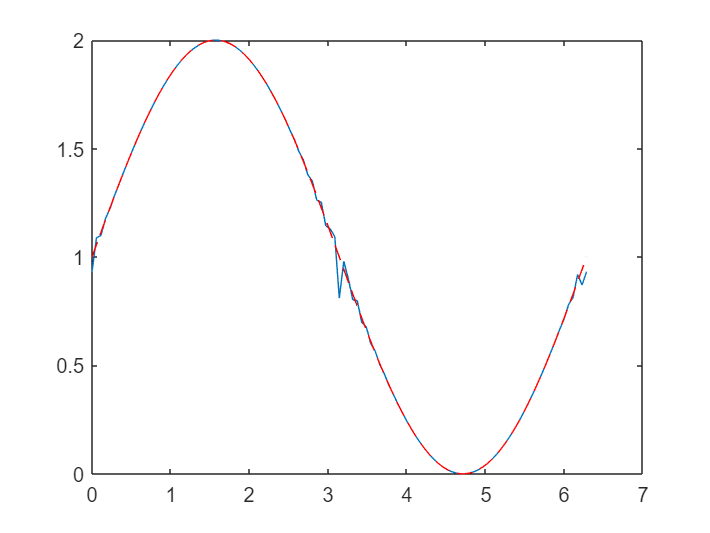

F = a*eye(Nx) + b/2*(diag(ones(Nx-1, 1), 1) + diag(ones(Nx-1, 1), -1));
G = eye(Nx) + c/2*(diag(ones(Nx-1, 1), 1) + diag(ones(Nx-1, 1), -1));

g = F\G * f(1:end-1).';

figure
plot(x_pl, [g; g(1)]);
hold on;
plot(x_pl, f_true, '--r')
hold off;